## Q4. Data-driven modelling

#### a. Centrality measures

#### i. Direct demand model

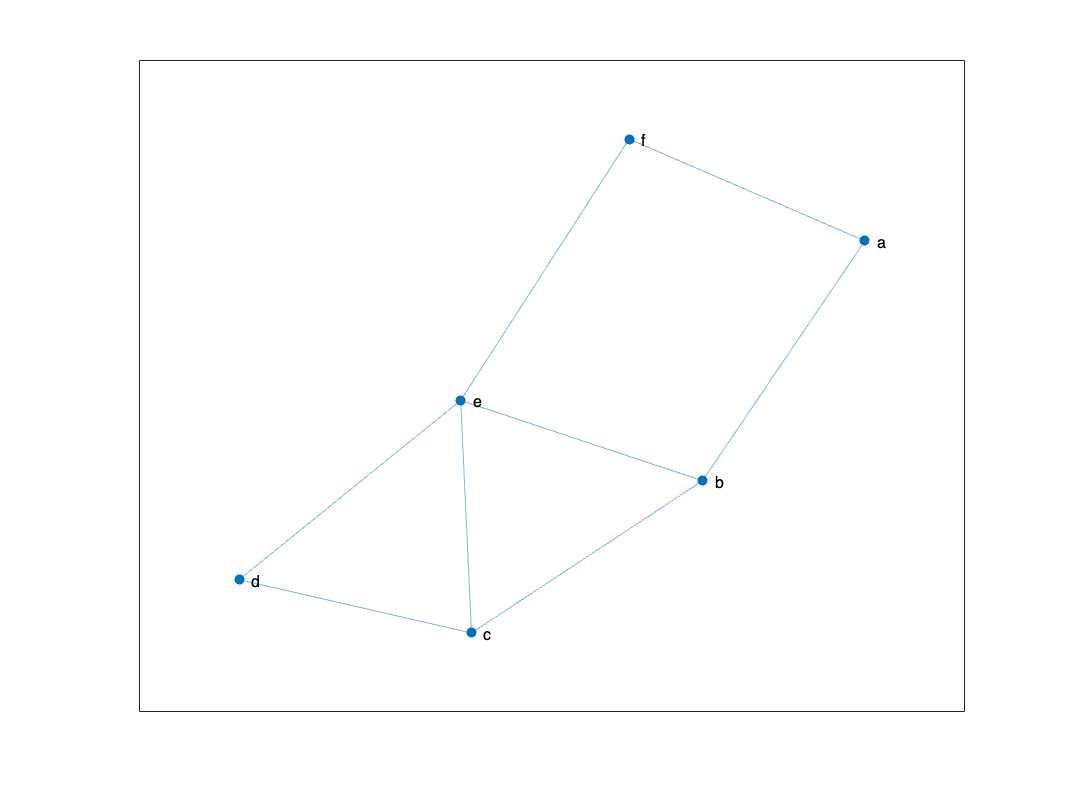

% The nodes are defined clockwise from top-left
clf;
% Create a graph
nodes = {'a','b','c','d','e','f'};
edges = {'a','b'; 'b','c'; 'c','d'; 'd','e'; 'e','f'; 'f','a'; 'c','e'; 'b','e'};
G = graph(edges(:, 1), edges(:, 2));
% Compute centralities
betweenness = centrality(G, 'betweenness');
degree = centrality(G, 'degree');
closeness = centrality(G, 'closeness');

% Known real values
real_val = [7,4.5,3,6,5.5,5.5];

% Plot the graph
plot(G, 'NodeLabel', G.Nodes.Name);

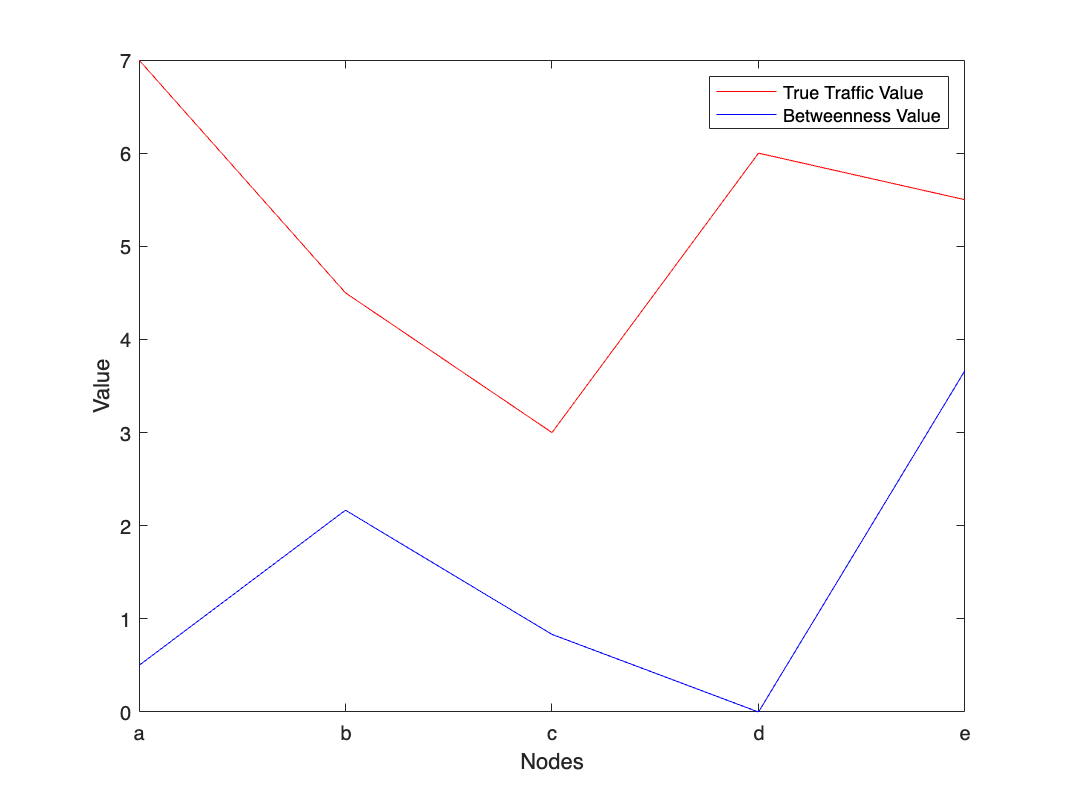

% plot the real values and betweenness
plot(1:5,real_val(1:5), 'Color','r', DisplayName='True Traffic Value')
hold on
plot(1:5,betweenness(1:5),'Color','b',DisplayName='Betweenness Value')
xticks(1:5)
xticklabels(nodes)
xlabel('Nodes')
ylabel('Value')
legend

% compare the correlation between
R = corr(real_val(1:5)',betweenness(1:5))

R = -0.1491

As shown in the graph, the betweenness value does not correlate very well with the true amount of traffic measured, with a correlation coefficient of 0.14 implying a weak correlation.

#### ii. Alternative model

Assume all lengths in graph = 1, using the inverse distance weighting


$$\rho_o =\frac{\sum_i \frac{\rho_i }{d_{\textrm{oi}} }\;}{\sum_i \frac{1}{d_{\textrm{oi}} }}$$


% for node f:
distances_f = [1,2,2,2,1]; % the distances of nodes from f (clockwise)
numerator = sum(real_val(1:5)./distances_f);
denominator = sum(ones(1,5)./distances_f);
prediction = numerator/denominator

prediction = 5.5000

error = prediction - real_val(6)

error = 0

#### b. Bristol road time series

#### i. Dynamics description

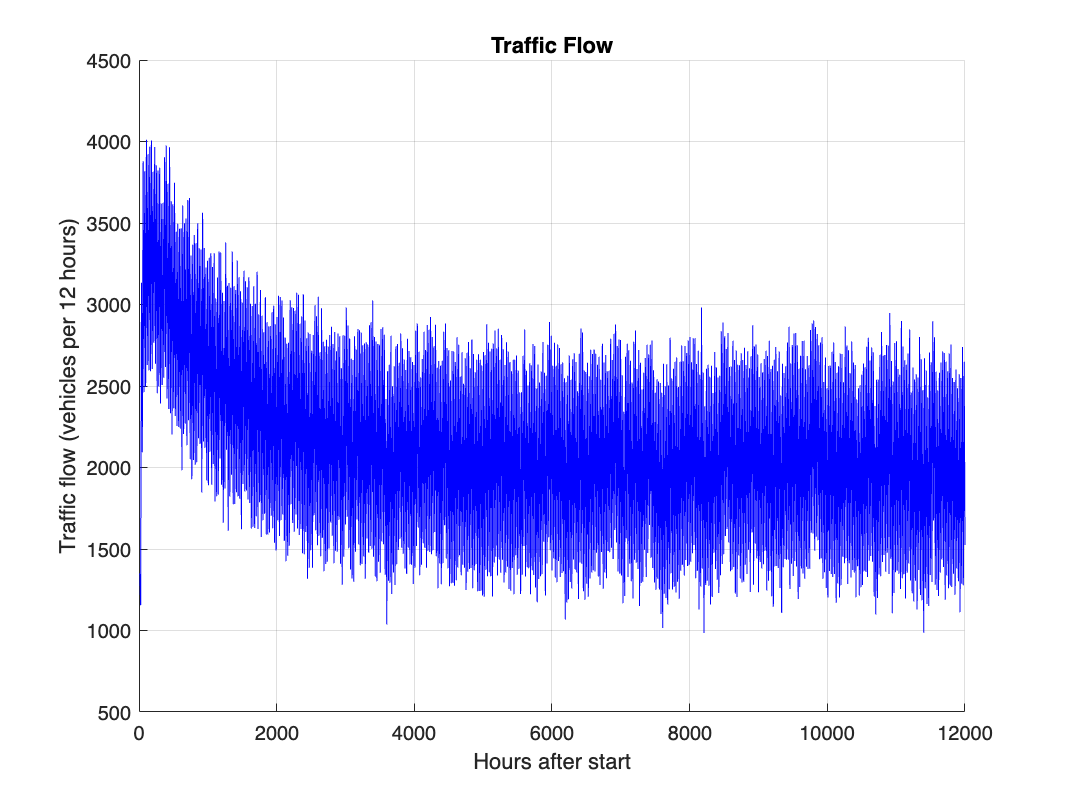

% define constants
alpha = 0.99;
beta = 0.5;
s = 4;
sigma = 0.1;

% starting conditions
Y_0 = 0;
a_0 = 0.75;
c_0 = 0.5;
% plot Y as a function of t
figure
hold on
timesteps = 1:1000;
vals = zeros(length(timesteps),3);
for t = timesteps
    [Y_1, a_1, c_1] = Y_t(alpha, beta, s, sigma, a_0, Y_0, c_0);
    Y_0 = Y_1;
    a_0 = a_1;
    c_0 = c_1;
    vals(t,:) = [Y_0, a_0,c_0];
end
hours = timesteps * 12;
vehicles = vals(:,1) * 1000;

plot(hours,vehicles, '-', Color='b');
xlabel('Hours after start')
ylabel('Traffic flow (vehicles per 12 hours)')
title('Traffic Flow');
grid on;
hold off;

This shows the traffic flow on the road in bristol. The traffic flow increases rapidly at the beginning up to a maximum of around 4000 vehicles / 12 hours and slowly decreases to a level of around 2000 vehicles / 12 hours at which it stays relatively constant into the future. The time series is noisy with the flow constantly varying.

#### ii. Discuss usefulness of model 

- The model should be validated against real traffic data from the Bristol road to assess its performance and identify areas for improvement.

- Another point of improve would be to include a further seasonal term for weekends, likely reducing the flow if its a commuter heavy road.

- When looking at the model for a smaller number of time steps it becomes clear that there is a seasonal term increasing during the day and decreasing during the night which would likely be fairly true to life.

% calculate the drift and diffusion of the data
% Fit a linear regression to estimate drift
X = [ones(length(timesteps), 1), hours'];
coefficients = X \ vehicles;
drift = coefficients(2)

drift = -0.0687

% Calculate residuals to estimate diffusion
residuals = vehicles - X * coefficients;
diffusion = std(residuals)

diffusion = 689.7461

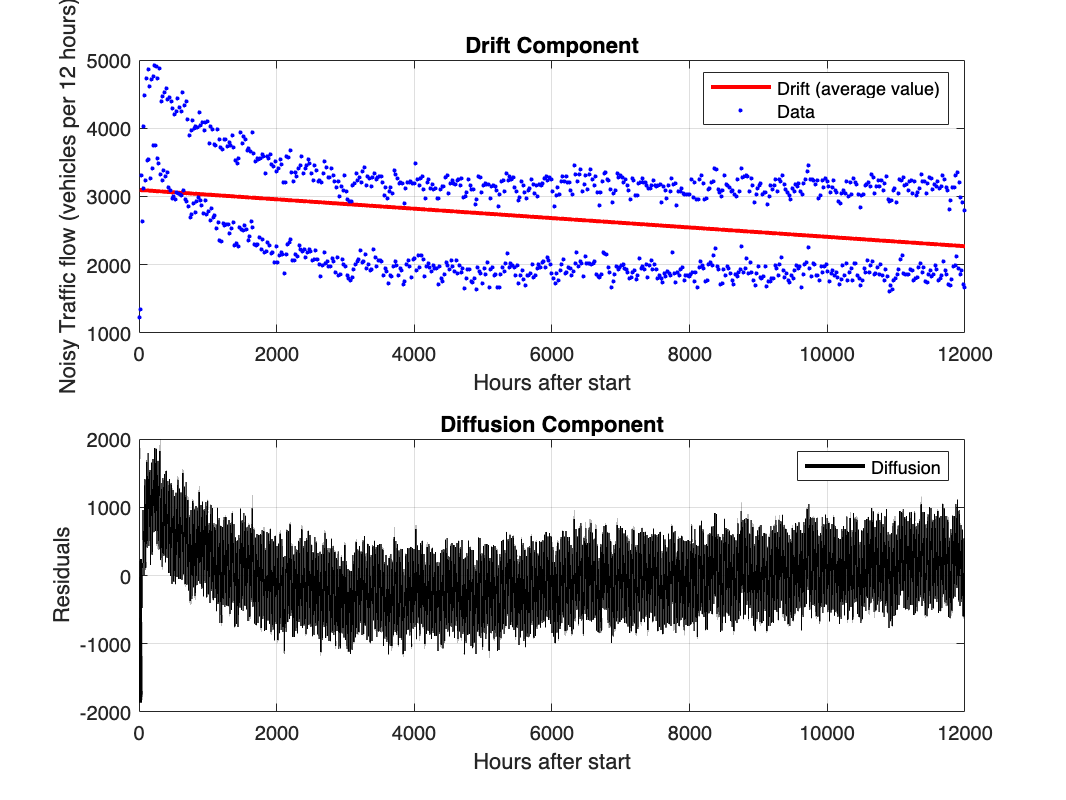

% Plot drift and diffusion components
figure;
subplot(2, 1, 1);
plot(hours, drift * hours + coefficients(1), 'r-', 'LineWidth', 2);
hold on;
scatter(hours, vehicles, 'b.');
xlabel('Hours after start');
ylabel('Noisy Traffic flow (vehicles per 12 hours)');
title('Drift Component');
legend('Drift (average value)','Data')
grid on;

subplot(2, 1, 2);
plot(hours, residuals, 'k-', 'LineWidth', 2);
xlabel('Hours after start');
ylabel('Residuals');
title('Diffusion Component');
legend('Diffusion')
grid on;

Drift: Represents the average rate of change of the traffic flow over time. This indicates that the traffic is gradually decreasing over time but only from the initial few hours. The drift term would likely be positive if only considering the long term model. This is likely inaccurate as traffic would likely stagnate at a level of equilibrium for that road.

Diffusion: Magnitude of randomness. Represents the random fluctuations or uncertainties in the traffic flow. This shows that initially there is a lot of randomness in the flow, which then quickly drops and then gradually increases. These fluctuations tend to show that for long term prediction the randomness is forcing the average up.

function [Y_1, a_1, c_1] = Y_t(alpha, beta, s, sigma, prev_a,prev_y, prev_c)

    a_1 = alpha * prev_a;
    b_1 = beta * prev_y;

    c = 0;
    for j = 1:(s/2)
        c = c + cos(2*pi*j*prev_c/s);
    end
    c_1 = c;

    d_1 = normrnd(0,sigma);

    Y_1 = a_1 + b_1 + c_1 + d_1;

end

